# readtable / treat missing values / specify import types

opts = detectImportOptions('trainData.csv');
opts.MissingRule = 'omitrow'; % missing values can cause problematic estimation results
% some functions are robust with missing data,
% while some are not

categoricalVariableNames = {'grade', 'emp_length', 'home_ownership',  ...
    'collections_12_mths_ex_med', 'application_type', 'acc_now_delinq'};
opts = setvartype(opts, categoricalVariableNames, 'categorical' );

opts = setvaropts(opts, 'emp_length', 'TreatAsMissing', {'n/a'});

% remove variables that have too many missing values
miss_var = {'mths_since_last_delinq'}; % this variable has 110000+ missing data
selected = setdiff(opts.VariableNames(3:end), miss_var);
opts.SelectedVariableNames = selected;

% readtable with options
trainTbl = readtable('trainData.csv', opts);

%convert loan_status to logical values
key = 'Charged Off';
trainTbl.loan_status = strcmpi(trainTbl.loan_status, key);

summary(trainTbl)

Variables:

    acc_now_delinq: 204380×1 categorical

        Values:

            0    2.0354e+05
            1           795
            2            44
            3             3
            5             2

    annual_inc: 204380×1 double

        Values:

            Min            60 
            Median      68000 
            Max       9.3e+06 

    application_type: 204380×1 categorical

        Values:

            Individual    1.9405e+05
            Joint App          10331

    collection_recovery_fee: 204380×1 double

        Values:

            Min             0 
            Median          0 
            Max        4807.5 

    collections_12_mths_ex_med: 204380×1 categorical

        Values:

            0    2.0097e+05
            1          3119
            2           224
            3            43
            4            11
            5             2
            6             4


% check variable levels to determine which variables are categorical
func = @(x) numel(unique(x));
varLevel = varfun(func,trainTbl);

% -------------------------------------------------------------------------
% similarly for testdata

testTbl = readtable('testData.csv', opts);

%convert loan_status to logical values
testTbl.loan_status = strcmpi(testTbl.loan_status, key);

summary(testTbl)
% -------------------------------------------------------------------------
% group predictor variables
predictorNames = setdiff(trainTbl.Properties.VariableNames, 'loan_status');
numVariableNames = setdiff(predictorNames, categoricalVariableNames); % numerical predictors

## convert categorical variables to dummy variables

because some functions such as corr(), ridge() and lassoglm() cannot deal with categorical predictors

% create dummy variable for 'grade'
grade_dum = dummyvar(trainTbl.grade);
grade_dum2 = dummyvar(testTbl.grade);
types = categories(trainTbl.grade);
dum_names = join([repmat({'grade'}, length(types), 1),types], '_' );
grade_trainTbl = array2table(grade_dum, 'VariableNames', dum_names);
grade_testTbl = array2table(grade_dum2, 'VariableNames', dum_names);

% create dummy variables for 'emp_length'
emp_length_dum = dummyvar(trainTbl.emp_length);
emp_length_dum2 = dummyvar(testTbl.emp_length);
types = categories(trainTbl.emp_length);
dum_names = join ([repmat({'emp_length'}, length(types), 1),types], '_' );
emp_length_trainTbl = array2table(emp_length_dum, 'VariableNames', dum_names);
emp_length_testTbl = array2table(emp_length_dum2, 'VariableNames', dum_names);

% create dummy variable for 'home_ownership'
home_ownership_dum = dummyvar(trainTbl.home_ownership);
home_ownership_dum2 = dummyvar(testTbl.home_ownership);
types = categories(trainTbl.home_ownership);
dum_names = join([repmat({'home_ownership'}, length(types), 1),types], '_' );
home_ownership_trainTbl = array2table(home_ownership_dum, 'VariableNames', dum_names);
home_ownership_testTbl = array2table(home_ownership_dum2, 'VariableNames', dum_names);

% create dummy variable for 'collections_12_mths_ex_med'
collections_12_mths_ex_med_dum = dummyvar(trainTbl.collections_12_mths_ex_med);
collections_12_mths_ex_med_dum2 = dummyvar(testTbl.collections_12_mths_ex_med);
types = categories(trainTbl.collections_12_mths_ex_med);
dum_names = join([repmat({'collections_12_mths_ex_med'}, length(types), 1),types], '_' );
collections_12_mths_ex_med_trainTbl = array2table(collections_12_mths_ex_med_dum, 'VariableNames', dum_names);
collections_12_mths_ex_med_testTbl = array2table(collections_12_mths_ex_med_dum2, 'VariableNames', dum_names);

% create dummy variable for 'application_type'
application_type_dum = dummyvar(trainTbl.application_type);
application_type_dum2 = dummyvar(testTbl.application_type);
types = categories(trainTbl.application_type);
dum_names = join([repmat({'application_type'}, length(types), 1),types], '_' );
application_type_trainTbl = array2table(application_type_dum, 'VariableNames', dum_names);
application_type_testTbl = array2table(application_type_dum2, 'VariableNames', dum_names);

% create dummy variable for 'acc_now_delinq'
acc_now_delinq_dum = dummyvar(trainTbl.acc_now_delinq);
acc_now_delinq_dum2 = dummyvar(testTbl.acc_now_delinq);
types = categories(trainTbl.acc_now_delinq);
dum_names = join([repmat({'acc_now_delinq'}, length(types), 1),types], '_' );
acc_now_delinq_trainTbl = array2table(acc_now_delinq_dum, 'VariableNames', dum_names);
acc_now_delinq_testTbl = array2table(acc_now_delinq_dum2, 'VariableNames', dum_names);


% create predictor table. Note that first column of dummy variables are
% used as reference level

Predictor_trainTbl = [trainTbl(:,numVariableNames), grade_trainTbl(:,2:end), ...
    emp_length_trainTbl(:,2:end), home_ownership_trainTbl(:,2:end), ...
    collections_12_mths_ex_med_trainTbl(:,2:end), ...
    application_type_trainTbl(:,2:end), acc_now_delinq_trainTbl(:,2:end) ];

Predictor_testTbl = [testTbl(:,numVariableNames), grade_testTbl(:,2:end), ...
    emp_length_testTbl(:,2:end), home_ownership_testTbl(:,2:end), ...
    collections_12_mths_ex_med_testTbl(:,2:end), ...
    application_type_testTbl(:,2:end), acc_now_delinq_testTbl(:,2:end) ];

new_trainTbl = [Predictor_trainTbl, trainTbl(:,{'loan_status'})];
new_testTbl = [Predictor_testTbl, testTbl(:,{'loan_status'})];

## preliminary analysis / covariance analysis

In this block, using the new_trainTbl to analyse the correlation between predicors and the response variable 'loan_status'. Use a heatmap to display the correlation structure. And find out the top 10 and bottom 10 correlated predictors, call them top10 and bottom10. Include the graph in your reporting. ######################################################################### -------------------------------------------------------------------------

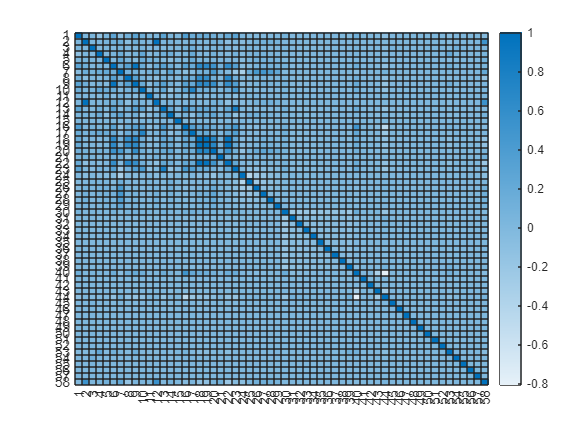

%                   write your code here
cor = corrcoef(table2array(new_trainTbl));
heatmap(cor);

cor_loan_status = cor(58, :);
cor_loan_status = cor_loan_status(1:57);
[out, sorted_idx] = sort(cor_loan_status);
top10 = new_trainTbl.Properties.VariableNames(sorted_idx(1:10))';
bottom10 = new_trainTbl.Properties.VariableNames(sorted_idx(48:57))';
% -------------------------------------------------------------------------
% #########################################################################

## GLS

estimate a logistical model using the trainTbl (i.e., contains categorical variables) ######################################################################### -------------------------------------------------------------------------

%                   write your code here
glsMdl = fitglm(new_trainTbl,  'linear', ...
    'Distribution', 'binomial');

% -------------------------------------------------------------------------
% #########################################################################

% forecast using training data, and compute glsMSE_train
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
glsForecast_train = predict(glsMdl, Predictor_trainTbl);
glsForecast_train = (glsForecast_train >=0.5);
glsMSE_train = mean((glsForecast_train - new_trainTbl.loan_status).^2);
fprintf('MSE of the GLS using training sample is: %6.4f \n', glsMSE_train);

MSE of the GLS using training sample is: 0.0576 


% -------------------------------------------------------------------------
% #########################################################################

% forecast using test data, and compute glsMSE_test
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
glsForecast_test = predict(glsMdl, Predictor_testTbl)

glsForecast_test =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


glsForecast_test = (glsForecast_test >=0.5);
glsMSE_test = mean((glsForecast_test - new_testTbl.loan_status).^2);
fprintf('MSE of the GLS using test sample is: %6.4f \n', glsMSE_test);

MSE of the GLS using test sample is: 0.0580 


% -------------------------------------------------------------------------
% #########################################################################

## stepwise regression models

Fit a stepwise regression model using only the top10 predictors you have found in the covariance analysis above.

swMdl = stepwiseglm(new_trainTbl(:,[top10; {'loan_status'}]),  'constant', 'upper', 'linear', ...
              'Distribution', 'binomial' );

1. Adding total_rec_prncp, Deviance = 130838.1194, Chi2Stat = 13596.00878, PValue = 0
2. Adding last_pymnt_amnt, Deviance = 125115.8736, Chi2Stat = 5722.245755, PValue = 0
3. Adding total_pymnt_inv, Deviance = 105724.2094, Chi2Stat = 19391.66427, PValue = 0
4. Adding application_type_Joint App, Deviance = 104006.6536, Chi2Stat = 1717.555791, PValue = 0
5. Adding total_rev_hi_lim, Deviance = 103728.9437, Chi2Stat = 277.7098681, PValue = 2.369532985e-62
6. Adding annual_inc, Deviance = 103614.5348, Chi2Stat = 114.4088887, PValue = 1.06027678e-26
7. Adding tot_cur_bal, Deviance = 103581.8902, Chi2Stat = 32.6445757, PValue = 1.106477795e-08
8. Adding total_pymnt, Deviance = 103557.8526, Chi2Stat = 24.03764452, PValue = 9.447051547e-07
9. Adding home_ownership_MORTGAGE, Deviance = 103548.613, Chi2Stat = 9.239580189, PValue = 0.002368392459



% forecast using training sample, and compute MSE for the training sample
swForecast_train = predict(swMdl, Predictor_trainTbl(:,top10));
swForecast_train = (swForecast_train >=0.5);
swMSE_train = mean((swForecast_train - trainTbl.loan_status).^2);
fprintf('MSE of the step-wise estimator using training sample is: %6.4f \n', swMSE_train);

MSE of the step-wise estimator using training sample is: 0.1022 




% forecast using testing sample, and compute MSE for the testing sample,
% call it swMSE_test.
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
swForecast_test = predict(swMdl, Predictor_testTbl(:, top10));
swForecast_test = (swForecast_test >= 0.5);
swMSE_test = mean((swForecast_test - testTbl.loan_status).^2);
fprintf('MSE of the step-wise estimator using test sample is: %6.4f \n', swMSE_test);

MSE of the step-wise estimator using test sample is: 0.1033 


% -------------------------------------------------------------------------
% #########################################################################

## lasso

model estimation using training data lasso cannot handle categorical predictors

[B_lasso,fitInfo] = lassoglm(Predictor_trainTbl{:,:}, trainTbl.loan_status, 'binomial', 'CV', 3);

B0 = fitInfo.Intercept(fitInfo.IndexMinDeviance);
coef = [B0; B_lasso(:, fitInfo.IndexMinDeviance)];

% predict loan_status using training sample
lassohat_train = glmval(coef, Predictor_trainTbl{:,:}, 'logit'); % specify 'logit' for binomial response
lassoForecast_train = (lassohat_train >=0.5);
lassoMSE_train = mean((lassoForecast_train -trainTbl.loan_status).^2);
fprintf('MSE of the lasso estimator using training sample is: %6.4f \n', lassoMSE_train);

MSE of the lasso estimator using training sample is: 0.0378 


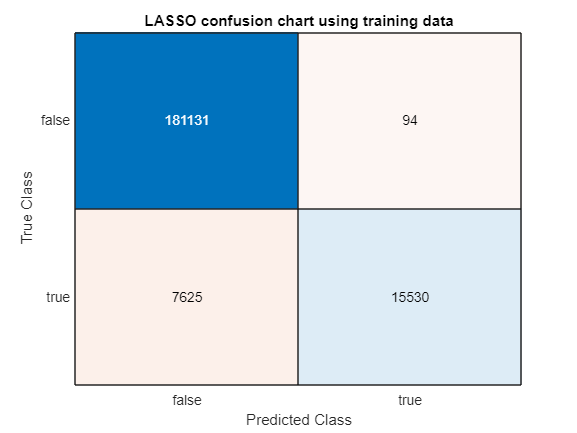

% output confusion chart for training sample
figure()
c_lasso_train = confusionchart(trainTbl.loan_status, lassoForecast_train);
title('LASSO confusion chart using training data')


% predict loan_status using testing sample. Hint: follow the method we used
% for training sample
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
lassohat_test = glmval(coef, Predictor_testTbl{:,:}, 'logit'); % specify 'logit' for binomial response
lassoForecast_test = (lassohat_test >=0.5);
lassoMSE_test = mean((lassoForecast_test -testTbl.loan_status).^2);
fprintf('MSE of the lasso estimator using training sample is: %6.4f \n', lassoMSE_test);

MSE of the lasso estimator using training sample is: 0.0389 


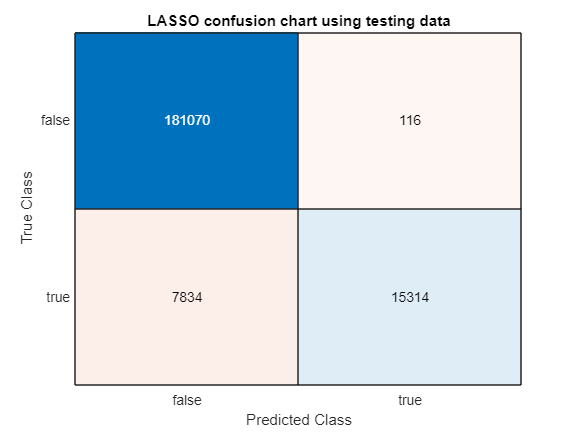

% -------------------------------------------------------------------------
% #########################################################################
% output confusion chart for testing sample
figure()
c_lasso_test = confusionchart(testTbl.loan_status, lassoForecast_test);
title('LASSO confusion chart using testing data')

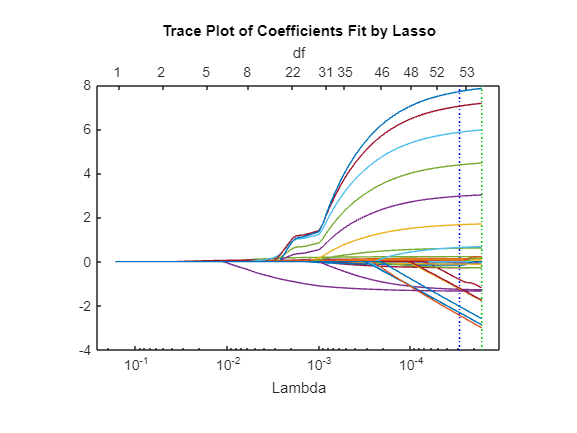


% plot the lasso coefficient (B_lasso)along lambda values, and save the figure
% as png file for reporting. You don't need to standarise the dataset.
figure()
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
lassoPlot(B_lasso, fitInfo, 'PlotType', 'Lambda', 'XScale', 'log');

% -------------------------------------------------------------------------
% #########################################################################

## Elastic Net

Do the same analysis as you did with the lasso, but use the elastic net model with alpha parameter set to 0.5. ######################################################################### -------------------------------------------------------------------------

%                   write your code here
[B_lassoEN,fitInfoEN] = lassoglm(Predictor_trainTbl{:,:}, trainTbl.loan_status, 'binomial', 'CV', 3, 'Alpha', .5);

B0EN = fitInfoEN.Intercept(fitInfoEN.IndexMinDeviance);
coefEN = [B0EN; B_lassoEN(:, fitInfoEN.IndexMinDeviance)];

% predict loan_status using training sample
ENhat_train = glmval(coefEN, Predictor_trainTbl{:,:}, 'logit'); % specify 'logit' for binomial response
ENForecast_train = (ENhat_train >=0.5);
EN_MSE_train = mean((ENForecast_train -trainTbl.loan_status).^2);
fprintf('MSE of the Elastic Net estimator using training sample is: %6.4f \n', ENForecast_train);

MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 1.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0000 
MSE of the Elastic Net estimator using training sample is: 0.0

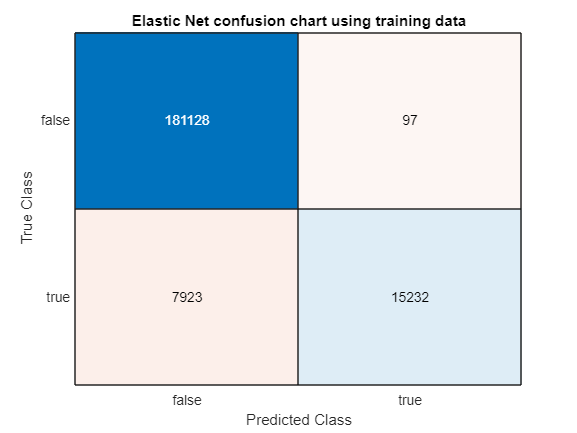

% output confusion chart for training sample
figure()
c_EN_train = confusionchart(trainTbl.loan_status, ENForecast_train);
title('Elastic Net confusion chart using training data')


% predict loan_status using testing sample. Hint: follow the method we used
% for training sample
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
ENhat_test = glmval(coefEN, Predictor_testTbl{:,:}, 'logit'); % specify 'logit' for binomial response
ENForecast_test = (ENhat_test >=0.5);
EN_MSE_test = mean((ENForecast_test -testTbl.loan_status).^2);
fprintf('MSE of the Elastic Net estimator using training sample is: %6.4f \n', EN_MSE_test);

MSE of the Elastic Net estimator using training sample is: 0.0403 


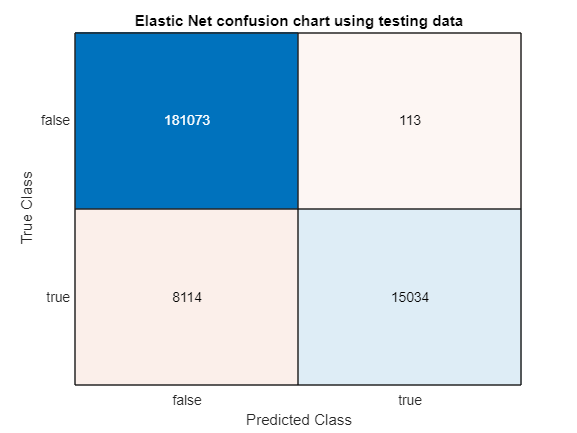

% -------------------------------------------------------------------------
% #########################################################################
% output confusion chart for testing sample
figure()
c_EN_test = confusionchart(testTbl.loan_status, ENForecast_test);
title('Elastic Net confusion chart using testing data')

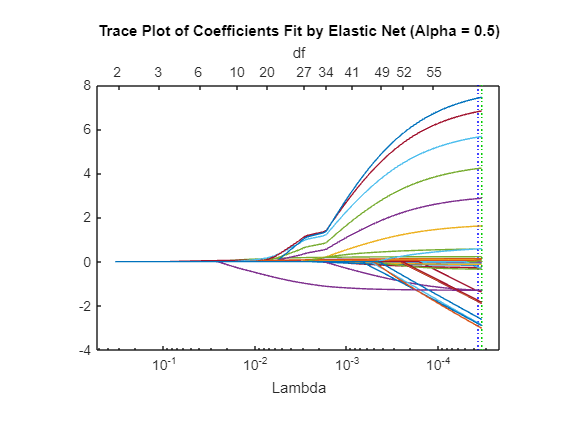


% plot the lasso coefficient (B_lasso)along lambda values, and save the figure
% as png file for reporting. You don't need to standarise the dataset.
figure()
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
lassoPlot(B_lassoEN, fitInfoEN, 'PlotType', 'Lambda', 'XScale', 'log');

% -------------------------------------------------------------------------
% #########################################################################
% -------------------------------------------------------------------------
% #########################################################################

## bagging

fit an ensemble model using bagging algo (using a tree as the weak learner. output the estimated model as 'bagMdl'.)

t = templateTree('MaxNumSplits', 5, 'PredictorSelection','interaction-curvature','Reproducible', true); % using curvature algo when include categorical predictors
% #########################################################################
% -------------------------------------------------------------------------

%                    write your code here
bagMdl = fitcensemble(trainTbl(:, predictorNames), trainTbl.loan_status, 'Method', 'Bag', 'Learners', t);
% -------------------------------------------------------------------------
% #########################################################################

% forecast using training sample
bagForecast_train = predict(bagMdl,trainTbl(:,predictorNames));
bagMSE_train = mean((bagForecast_train - trainTbl.loan_status).^2);
fprintf('MSE of the bagging ensemble estimator using training sample is: %6.4f \n', bagMSE_train);

MSE of the bagging ensemble estimator using training sample is: 0.0368 


% forecast using testing sample, and save MSE as bagMSE_test
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
bagForecast_test = predict(bagMdl,testTbl(:,predictorNames));
bagMSE_test = mean((bagForecast_test - testTbl.loan_status).^2);
% -------------------------------------------------------------------------
% #########################################################################
fprintf('MSE of the bagging ensemble estimator using testing sample is: %6.4f \n', bagMSE_test);

MSE of the bagging ensemble estimator using testing sample is: 0.0380 


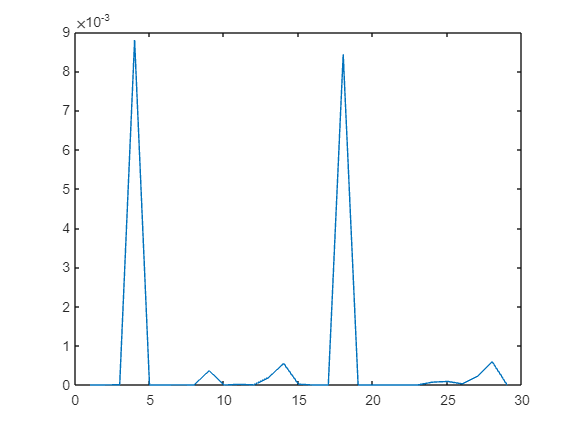


% predictor importance estimation
% note 'PredictorSelection','interaction-curvature' ensures importance is
% not baised towards variables with many levels
imp = bagMdl.predictorImportance;
figure();
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
plot(imp);

% -------------------------------------------------------------------------
% #########################################################################

% find top 10 important predictors
bagImportanceTbl = array2table(abs(imp)', 'RowNames', bagMdl.PredictorNames, 'VariableNames', {'abs_coef'});
bagImportanceTbl = sortrows(bagImportanceTbl);
bagTop10 = bagImportanceTbl.Properties.RowNames(end-9:end);
disp(bagTop10)

    {'total_rec_int'          }
    {'total_pymnt'            }
    {'total_pymnt_inv'        }
    {'int_rate'               }
    {'total_rec_late_fee'     }
    {'grade'                  }
    {'last_pymnt_amnt'        }
    {'total_rec_prncp'        }
    {'recoveries'             }
    {'collection_recovery_fee'}



## boosting

fit a boosting ensemble model using a tree as the weak learner. It is very similar to the procedure above. Save MSE for the training and testing sample as boostMSE_train and boostMSE_test, respectively. Find the top 10 important predictors. ######################################################################### -------------------------------------------------------------------------

%                   write your code here
t = templateTree('MaxNumSplits', 5, 'PredictorSelection','interaction-curvature','Reproducible', true); % using curvature algo when include categorical predictors
% #########################################################################
% -------------------------------------------------------------------------

%                    write your code here
boostMdl = fitcensemble(trainTbl(:, predictorNames), trainTbl.loan_status, 'Method', 'AdaBoostM1', 'Learners', t);
% -------------------------------------------------------------------------
% #########################################################################

% forecast using training sample
boostForecast_train = predict(boostMdl,trainTbl(:,predictorNames));
boostMSE_train = mean((boostForecast_train - trainTbl.loan_status).^2);
fprintf('MSE of the boosting ensemble estimator using training sample is: %6.4f \n', boostMSE_train);

MSE of the boosting ensemble estimator using training sample is: 0.0353 



% forecast using testing sample, and save MSE as boostMSE_test
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
boostForecast_test = predict(boostMdl,testTbl(:,predictorNames));
boostMSE_test = mean((boostForecast_test - testTbl.loan_status).^2);
% -------------------------------------------------------------------------
% #########################################################################
fprintf('MSE of the boosting ensemble estimator using testing sample is: %6.4f \n', boostMSE_test);

MSE of the boosting ensemble estimator using testing sample is: 0.0364 


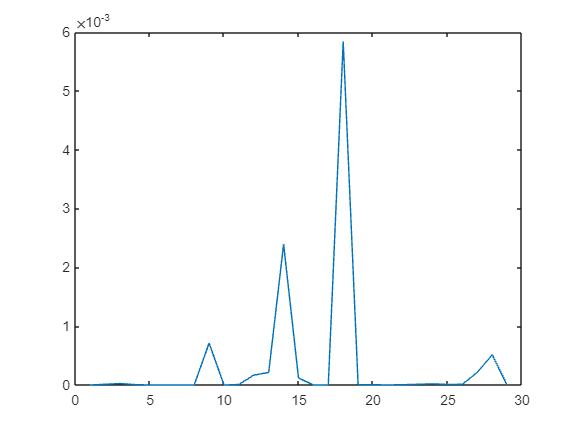


% predictor importance estimation
% note 'PredictorSelection','interaction-curvature' ensures importance is
% not baised towards variables with many levels
imp = boostMdl.predictorImportance;
figure();
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
plot(imp);


% -------------------------------------------------------------------------
% #########################################################################

% find top 10 important predictors
boostImportanceTbl = array2table(abs(imp)', 'RowNames', boostMdl.PredictorNames, 'VariableNames', {'abs_coef'});
boostImportanceTbl = sortrows(boostImportanceTbl);
boostTop10 = boostImportanceTbl.Properties.RowNames(end-9:end);
disp(boostTop10)

    {'total_pymnt'       }
    {'application_type'  }
    {'loan_amnt'         }
    {'installment'       }
    {'int_rate'          }
    {'total_rec_late_fee'}
    {'total_rec_prncp'   }
    {'grade'             }
    {'last_pymnt_amnt'   }
    {'recoveries'        }



% -------------------------------------------------------------------------
% #########################################################################

## random forest

fit a random forest with 50 trees. Randomly select 1/3 of total predictors to build each tree. Name this model rfMdl. ######################################################################### -------------------------------------------------------------------------

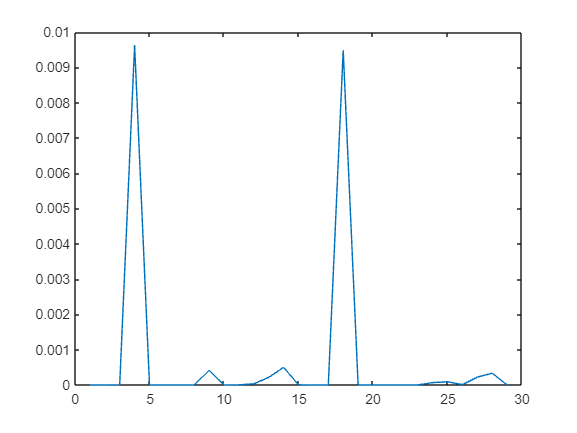

%                   write your code here
% rfMdl = TreeBagger(50, trainTbl(:, predictorNames), trainTbl.loan_status, 'NumPredictorsToSample', 10, OOBPredictorImportance='on');
t = templateTree('MaxNumSplits', 5, 'PredictorSelection','interaction-curvature','Reproducible', true);
rfMdl = fitcensemble(trainTbl(:, predictorNames), trainTbl.loan_status, 'Method', 'Bag', 'NumLearningCycles', 50, 'Learners', t);
% -------------------------------------------------------------------------
% #########################################################################
% MSE using training sample
rfForecast_train = predict(rfMdl, trainTbl(:,predictorNames)); % output is a cell array -> convert to numeric vector
% rfForecast_train = cellfun(@str2double, rfForecast_train);
rfMSE_train = mean((rfForecast_train - trainTbl.loan_status).^2);
% MSE using testing sample
rfForecast_test = predict(rfMdl, testTbl(:,predictorNames));
% rfForecast_test = cellfun(@str2double, rfForecast_test);
rfMSE_test = mean((rfForecast_test - testTbl.loan_status).^2);

% Predictor importance estimation
% #########################################################################
% -------------------------------------------------------------------------

%                   write your code here
imp = rfMdl.predictorImportance;
figure();
plot(imp);

% -------------------------------------------------------------------------
% #########################################################################

## save data

save('assignment.mat', 'trainTbl','testTbl', 'top10', 'bottom10','glsMSE_train', 'glsMSE_test', ...
    'swMSE_train', 'swMSE_test', 'lassoMSE_train', 'lassoMSE_test', 'EN_MSE_train', 'EN_MSE_test',  ...
    'bagMSE_test', 'bagMSE_train', 'boostMSE_train', 'boostMSE_test', 'rfMSE_train', 'rfMSE_test');
% change the .mat file name as firstname_surname_ID.mat.